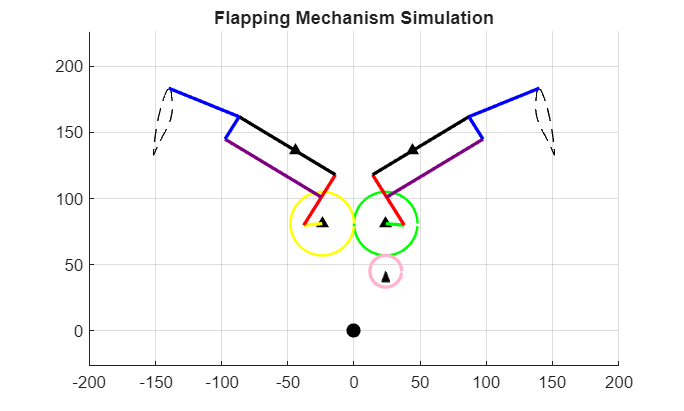

clear all;
clc;
close all;


% --- 1. DIMENSIONS & CONFIGURATION ---
l2 = 14; 
l3 = 45; 
l4 = 25; 
l5 = 85; 
l6 = 35; 
l7 = 85; 
l8 = 20; 
l9 = 57.5; 
l10 = 50;
PitchRadius = 24; 
GearBaseX = 24;   
PinionRadius = 12; 
Y_OFFSET = 81;             % Height Offset
Alpha = deg2rad(10.05);    % Tip angle adjustment


% Convert 150 rpm to rad/s
omega_input = 75 * (2*pi) / 60; 


% --- 2. PIVOT POINTS ---
O2_R_X = GearBaseX; 
O2_R_Y = 0 + Y_OFFSET; 
O6_R_X = GearBaseX + 20; 
O6_R_Y = 55 + Y_OFFSET; 


O2_L_X = -GearBaseX; 
O2_L_Y = 0 + Y_OFFSET; 
O6_L_X = -GearBaseX - 20; 
O6_L_Y = 55 + Y_OFFSET; 


% --- 3. KINEMATICS SOLVING (FIXED: GEOMETRIC METHOD) ---
% We replace 'solve' with explicit geometry to eliminate spikes
syms theta_2 real; 


% 1. Crank Tip (Point A)
Ax_R = O2_R_X + l2*cos(theta_2);
Ay_R = O2_R_Y + l2*sin(theta_2);


% 2. Distance from A to Pivot O6
dx = O6_R_X - Ax_R;
dy = O6_R_Y - Ay_R;
dist_sq = dx^2 + dy^2;
dist = sqrt(dist_sq);


% 3. Law of Cosines for internal angles
% Angle 'a' is part of the triangle formed by l3, l6, and the diagonal
a_dist = (l3^2 - l6^2 + dist_sq) / (2*dist);
h_dist = sqrt(l3^2 - a_dist^2); % Height of triangle


% 4. Find Intersection Point B (The Joint)
% Base point on the connecting line
x2 = Ax_R + a_dist * (O6_R_X - Ax_R) / dist;
y2 = Ay_R + a_dist * (O6_R_Y - Ay_R) / dist;


% Offset to find the actual intersection (We force the negative solution for stability)
BxNew_R = x2 - h_dist * (O6_R_Y - Ay_R) / dist;
ByNew_R = y2 + h_dist * (O6_R_X - Ax_R) / dist;


% 5. Extract Stable Angles
theta3_sol_R = atan2(ByNew_R - O6_R_Y, BxNew_R - O6_R_X); % Angle of Link 6
theta4_sol_R = atan2(ByNew_R - Ay_R, BxNew_R - Ax_R);     % Angle of Link 3


% --- Define Points (Right) ---
% (These are now calculated using the stable BxNew_R directly)
B_ext_X_R = O6_R_X - l10*cos(theta3_sol_R);
B_ext_Y_R = O6_R_Y - l10*sin(theta3_sol_R);


Cx_R = Ax_R + l4*(BxNew_R - Ax_R)/l3;
Cy_R = Ay_R + l4*(ByNew_R - Ay_R)/l3;


P_top_X_R = BxNew_R - l5*cos(theta3_sol_R);
P_top_Y_R = ByNew_R - l5*sin(theta3_sol_R);
P_bot_X_R = Cx_R - l7*cos(theta3_sol_R);
P_bot_Y_R = Cy_R - l7*sin(theta3_sol_R);


% *** Apply Tip Angle Adjustment ***
Tip_X_R = P_top_X_R + l9*sin(theta4_sol_R - Alpha);
Tip_Y_R = P_top_Y_R - l9*cos(theta4_sol_R - Alpha);


% Define Points (Left - Mirrored)
Ax_L = -Ax_R; Ay_L = Ay_R;
BxNew_L = -BxNew_R; ByNew_L = ByNew_R;
B_ext_X_L = -B_ext_X_R; B_ext_Y_L = B_ext_Y_R;
Cx_L = -Cx_R; Cy_L = Cy_R;
P_top_X_L = -P_top_X_R; P_top_Y_L = P_top_Y_R;
P_bot_X_L = -P_bot_X_R; P_bot_Y_L = P_bot_Y_R;
Tip_X_L = -Tip_X_R; Tip_Y_L = Tip_Y_R;


% --- 4. VELOCITY CALCULATION ---
V_Tip_X_R_expr = diff(Tip_X_R, theta_2);
V_Tip_Y_R_expr = diff(Tip_Y_R, theta_2);


Vx_R = V_Tip_X_R_expr * omega_input;
Vy_R = V_Tip_Y_R_expr * omega_input;


% Create numerical functions
f_Tip_X_R = matlabFunction(Tip_X_R);
f_Tip_Y_R = matlabFunction(Tip_Y_R);
f_Vx_R = matlabFunction(Vx_R);
f_Vy_R = matlabFunction(Vy_R);


% --- 5. ANIMATION SETUP ---
h_link2_R = @(t) plot([O2_R_X subs(Ax_R,t)],[O2_R_Y subs(Ay_R,t)],"-g", 'LineWidth', 2); 
h_link3_R = @(t) plot([subs(Ax_R,t) subs(BxNew_R,t)],[subs(Ay_R,t) subs(ByNew_R,t)],"-r", 'LineWidth', 2); 
h_link6_R = @(t) plot([subs(B_ext_X_R,t) subs(BxNew_R,t)],[subs(B_ext_Y_R,t) subs(ByNew_R,t)],"-k", 'LineWidth', 2);  
h_link5_R = @(t) plot([subs(BxNew_R,t) subs(P_top_X_R,t)],[subs(ByNew_R,t) subs(P_top_Y_R,t)],"-k", 'LineWidth', 2); 
h_link7_R = @(t) plot([subs(Cx_R,t) subs(P_bot_X_R,t)],[subs(Cy_R,t) subs(P_bot_Y_R,t)],'Color',[0.5 0 0.5], 'LineWidth', 2); 
h_link8_R = @(t) plot([subs(P_top_X_R,t) subs(P_bot_X_R,t)],[subs(P_top_Y_R,t) subs(P_bot_Y_R,t)],'-b', 'LineWidth', 2); 
h_link9_R = @(t) plot([subs(P_top_X_R,t) subs(Tip_X_R,t)],[subs(P_top_Y_R,t) subs(Tip_Y_R,t)],'-b', 'LineWidth', 2); 


h_link2_L = @(t) plot([O2_L_X subs(Ax_L,t)],[O2_L_Y subs(Ay_L,t)],"-y", 'LineWidth', 2); 
h_link3_L = @(t) plot([subs(Ax_L,t) subs(BxNew_L,t)],[subs(Ay_L,t) subs(ByNew_L,t)],"-r", 'LineWidth', 2); 
h_link6_L = @(t) plot([subs(B_ext_X_L,t) subs(BxNew_L,t)],[subs(B_ext_Y_L,t) subs(ByNew_L,t)],"-k", 'LineWidth', 2);  
h_link5_L = @(t) plot([subs(BxNew_L,t) subs(P_top_X_L,t)],[subs(ByNew_L,t) subs(P_top_Y_L,t)],"-k", 'LineWidth', 2); 
h_link7_L = @(t) plot([subs(Cx_L,t) subs(P_bot_X_L,t)],[subs(Cy_L,t) subs(P_bot_Y_L,t)],'Color',[0.5 0 0.5], 'LineWidth', 2); 
h_link8_L = @(t) plot([subs(P_top_X_L,t) subs(P_bot_X_L,t)],[subs(P_top_Y_L,t) subs(P_bot_Y_L,t)],'-b', 'LineWidth', 2); 
h_link9_L = @(t) plot([subs(P_top_X_L,t) subs(Tip_X_L,t)],[subs(P_top_Y_L,t) subs(Tip_Y_L,t)],'-b', 'LineWidth', 2); 


figure()
hold on 
title('Flapping Mechanism Simulation')
plot(O2_R_X, O2_R_Y, "^k", 'MarkerFaceColor','k');
plot(O6_R_X, O6_R_Y, "^k", 'MarkerFaceColor','k');
plot(O2_L_X, O2_L_Y, "^k", 'MarkerFaceColor','k');
plot(O6_L_X, O6_L_Y, "^k", 'MarkerFaceColor','k');
plot(0, 0, 'ok', 'MarkerFaceColor','k', 'MarkerSize', 8);


% Pitch Circles
t_circle_gear = 0:0.1:2*pi;
plot(O2_R_X + PitchRadius*cos(t_circle_gear), O2_R_Y + PitchRadius*sin(t_circle_gear), '-g', 'LineWidth', 1.5);
plot(O2_L_X + PitchRadius*cos(t_circle_gear), O2_L_Y + PitchRadius*sin(t_circle_gear), '-y', 'LineWidth', 1.5);


PinionCenterX = O2_R_X; PinionCenterY = O2_R_Y - PitchRadius - PinionRadius;
plot(PinionCenterX + PinionRadius*cos(t_circle_gear), PinionCenterY + PinionRadius*sin(t_circle_gear), '-', 'Color', [1 0.7 0.8], 'LineWidth', 2);


% Add Black Triangle at Pinion Center
tri_w = 6; tri_h = 8;
fill([PinionCenterX, PinionCenterX-tri_w/2, PinionCenterX+tri_w/2], ...
     [PinionCenterY, PinionCenterY-tri_h, PinionCenterY-tri_h], 'k');


% Tip Path Preview
t_range = 0:0.1:2*pi;
plot(subs(Tip_X_R,t_range),subs(Tip_Y_R,t_range),"--k") 
plot(subs(Tip_X_L,t_range),subs(Tip_Y_L,t_range),"--k") 


% Add Animators
fanimator(h_link2_R); fanimator(h_link3_R); fanimator(h_link6_R); fanimator(h_link5_R); fanimator(h_link7_R); fanimator(h_link8_R); fanimator(h_link9_R);
fanimator(h_link2_L); fanimator(h_link3_L); fanimator(h_link6_L); fanimator(h_link5_L); fanimator(h_link7_L); fanimator(h_link8_L); fanimator(h_link9_L);


hold off; axis equal; grid on
playAnimation('AnimationRange', [0 2*pi])



% --- 6. ANALYSIS: POSITION EXTREMES ---
t_range_analysis = 0:0.01:4*pi; 
t_range_deg = rad2deg(t_range_analysis);


Tip_X_R_values = f_Tip_X_R(t_range_analysis);
Tip_Y_R_values = f_Tip_Y_R(t_range_analysis);


fprintf('1. Extreme Position Analysis\n');

1. Extreme Position Analysis




% 1. Highest Point (Max Y)
[maxY, idxY_max] = max(Tip_Y_R_values);
angleY_max = t_range_deg(idxY_max);
fprintf('1. Highest Tip Position (Max Y):\n');

1. Highest Tip Position (Max Y):


fprintf('   Value: %.2f mm\n', maxY);

   Value: 183.69 mm


fprintf('   Angle: %.1f degrees\n', angleY_max);

   Angle: 347.2 degrees




% 2. Lowest Point (Min Y)
[minY, idxY_min] = min(Tip_Y_R_values);
angleY_min = t_range_deg(idxY_min);
fprintf('2. Lowest Tip Position (Min Y):\n');

2. Lowest Tip Position (Min Y):


fprintf('   Value: %.2f mm\n', minY);

   Value: 133.00 mm


fprintf('   Angle: %.1f degrees\n', angleY_min);

   Angle: 495.6 degrees




% 3. Widest Point (Max X for the right wing)
[maxX, idxX_max] = max(Tip_X_R_values);
angleX_wide = t_range_deg(idxX_max);
fprintf('3. Widest Tip Position (Max X on Right Side):\n');

3. Widest Tip Position (Max X on Right Side):


fprintf('   Value: %.2f mm\n', maxX);

   Value: 151.47 mm


fprintf('   Angle: %.1f degrees\n', angleX_wide);

   Angle: 124.3 degrees




% --- 7. POSITION vs TIME (0-5 sec) ---
fprintf('\nPlotting Vertical Position vs Time (0-5s)...\n');


Plotting Vertical Position vs Time (0-5s)...


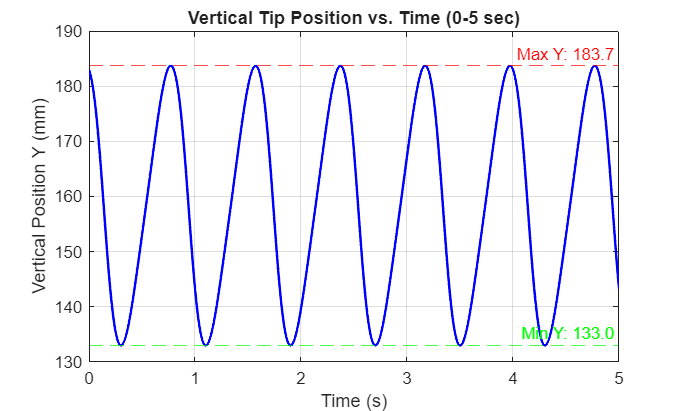



% Time Vector
t_simulation = 0:0.001:5; 
theta_input_time = omega_input * t_simulation;


% Calculate Y-Position over time
Y_time_vals = f_Tip_Y_R(theta_input_time);


figure()
plot(t_simulation, Y_time_vals, 'b-', 'LineWidth', 1.5);
hold on
yline(maxY, '--r', ['Max Y: ' num2str(maxY, '%.1f')]);
yline(minY, '--g', ['Min Y: ' num2str(minY, '%.1f')]);
hold off
title('Vertical Tip Position vs. Time (0-5 sec)')
xlabel('Time (s)')
ylabel('Vertical Position Y (mm)')
grid on
xlim([0 5])



% --- 8. VELOCITY vs TIME (Spikes Fixed naturally) ---
Vx_time_vals = f_Vx_R(theta_input_time);
Vy_time_vals = f_Vy_R(theta_input_time);
Speed_time_vals = sqrt(Vx_time_vals.^2 + Vy_time_vals.^2);


% Note: The noise filter loop is removed because the spike is gone.
% The data is now naturally smooth.


fprintf('Plotting Velocity vs Time (0-5s)\n');

Plotting Velocity vs Time (0-5s)


figure()
plot(t_simulation, Speed_time_vals, 'k-', 'LineWidth', 1.5);

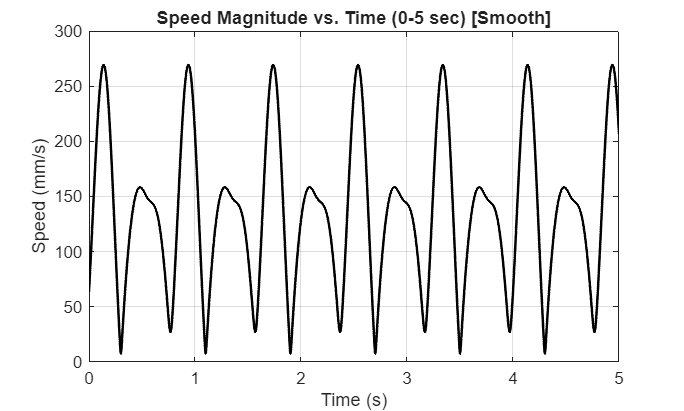

title('Speed Magnitude vs. Time (0-5 sec) [Smooth]');
xlabel('Time (s)'); ylabel('Speed (mm/s)'); grid on; xlim([0 5]);





% --- 9. HORIZONTAL POSITION vs TIME (0-5 sec) ---
% (Restored this section which was previously deleted)
fprintf('\nPlotting Horizontal Position vs Time (0-5s)...\n');


Plotting Horizontal Position vs Time (0-5s)...


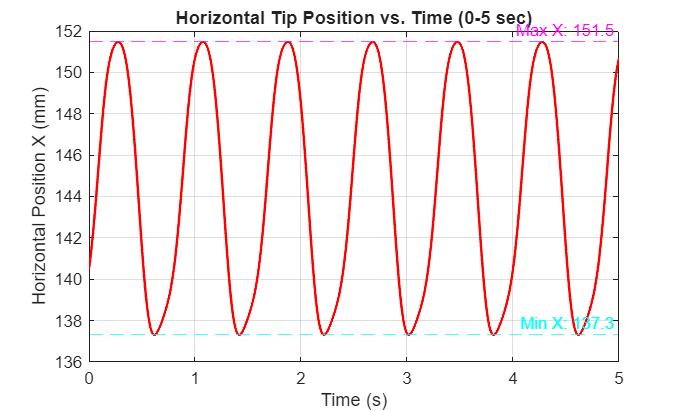



% Calculate X-Position over time
X_time_vals = f_Tip_X_R(theta_input_time);


[maxX_plot, ~] = max(X_time_vals);
[minX_plot, ~] = min(X_time_vals);


figure()
plot(t_simulation, X_time_vals, 'r-', 'LineWidth', 1.5);
hold on
xline_max_label = sprintf('Max X: %.1f', maxX_plot);
xline_min_label = sprintf('Min X: %.1f', minX_plot);
yline(maxX_plot, '--m', xline_max_label);
yline(minX_plot, '--c', xline_min_label);
hold off
title('Horizontal Tip Position vs. Time (0-5 sec)')
xlabel('Time (s)')
ylabel('Horizontal Position X (mm)')
grid on
xlim([0 5])



% --- 10. NEW: VELOCITY COMPONENTS X & Y vs TIME (0-5 sec) ---
fprintf('Plotting Velocity Components (Vx, Vy) vs Time (0-5s)...\n');

Plotting Velocity Components (Vx, Vy) vs Time (0-5s)...



figure()
hold on
plot(t_simulation, Vx_time_vals, 'r-', 'LineWidth', 1.5);

plot(t_simulation, Vy_time_vals, 'b-', 'LineWidth', 1.5);

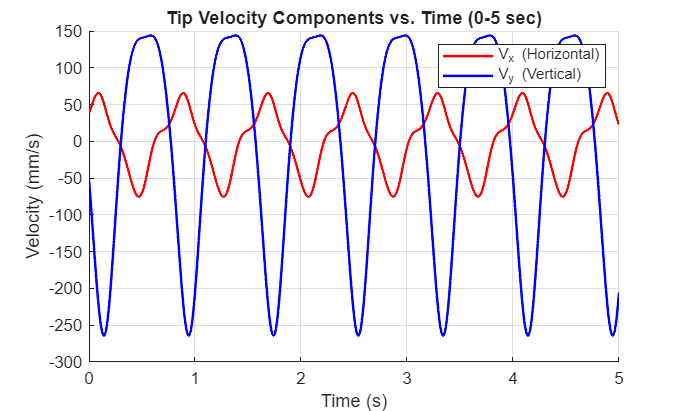

hold off
title('Tip Velocity Components vs. Time (0-5 sec)')
xlabel('Time (s)')
ylabel('Velocity (mm/s)')
legend('V_x (Horizontal)', 'V_y (Vertical)')
grid on
xlim([0 5])



% --- **START OF ANALYSIS (0-720 deg) FOR RIGHT WING** ---
% Create a high-resolution range from 0 to 4*pi (720 deg)
t_range_analysis = 0:0.01:4*pi; 
t_range_deg = rad2deg(t_range_analysis);


fprintf('Analyzing RIGHT TIP extreme positions from 0 to 720 degrees...\n');

Analyzing RIGHT TIP extreme positions from 0 to 720 degrees...


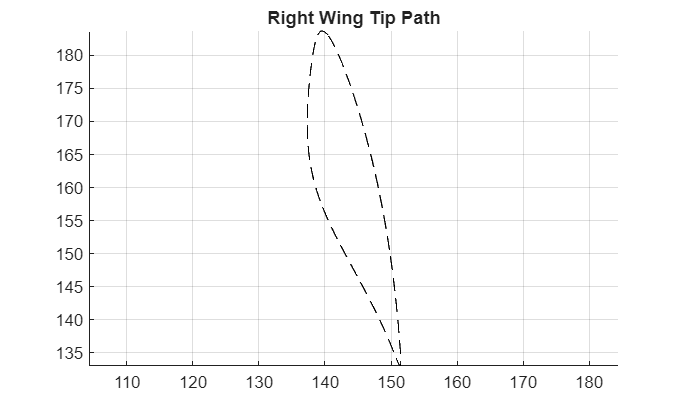



% Calculate values for 0-720
Tip_X_R_values = f_Tip_X_R(t_range_analysis);
Tip_Y_R_values = f_Tip_Y_R(t_range_analysis);


% --- Plot Path ---
figure()
hold on 
title('Right Wing Tip Path')
% Plot path for 0-360 degrees
t_range = 0:0.01:2*pi;
plot(subs(Tip_X_R,t_range),subs(Tip_Y_R,t_range),"--k") 
hold off
axis equal; grid on



% --- PLOT POSITION (X and Y) vs ANGLE (RIGHT TIP) ---
fprintf('Plotting Position (X/Y) graphs for RIGHT TIP...\n');

Plotting Position (X/Y) graphs for RIGHT TIP...


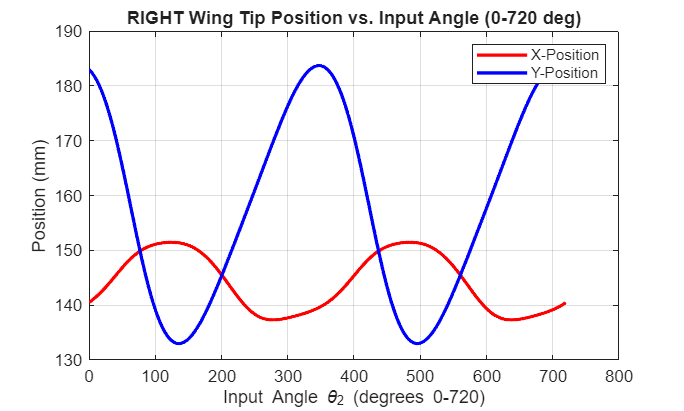



figure()
plot(t_range_deg, Tip_X_R_values, 'r-', 'LineWidth', 2)
grid on
hold on
plot(t_range_deg, Tip_Y_R_values, 'b-', 'LineWidth', 2)
title('RIGHT Wing Tip Position vs. Input Angle (0-720 deg)')
xlabel('Input Angle \theta_2 (degrees 0-720)')
ylabel('Position (mm)')
legend('X-Position','Y-Position')



% --- PLOT VELOCITY (Vx and Vy) (RIGHT TIP) ---
fprintf('Plotting Velocity (Vx/Vy) graph for RIGHT TIP...\n');

Plotting Velocity (Vx/Vy) graph for RIGHT TIP...




Vx_values = f_Vx_R(t_range_analysis);
Vy_values = f_Vy_R(t_range_analysis);


figure() 
hold on
plot(t_range_deg, Vx_values, 'r-', 'LineWidth', 2)

plot(t_range_deg, Vy_values, 'b-', 'LineWidth', 2)

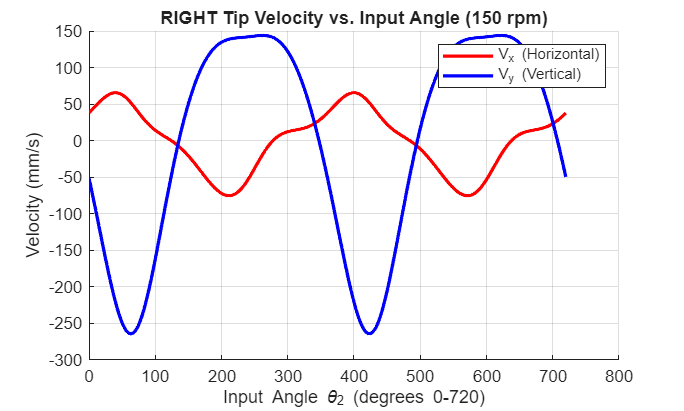

hold off
title('RIGHT Tip Velocity vs. Input Angle (150 rpm)')
xlabel('Input Angle \theta_2 (degrees 0-720)')
ylabel('Velocity (mm/s)')
legend('V_x (Horizontal)', 'V_y (Vertical)')
grid on



% --- PLOT SPEED (Magnitude) (RIGHT TIP) ---
fprintf('Plotting Speed graph for RIGHT TIP...\n');

Plotting Speed graph for RIGHT TIP...




Speed_values = sqrt(Vx_values.^2 + Vy_values.^2);


figure()
plot(t_range_deg, Speed_values, 'k-', 'LineWidth', 2)

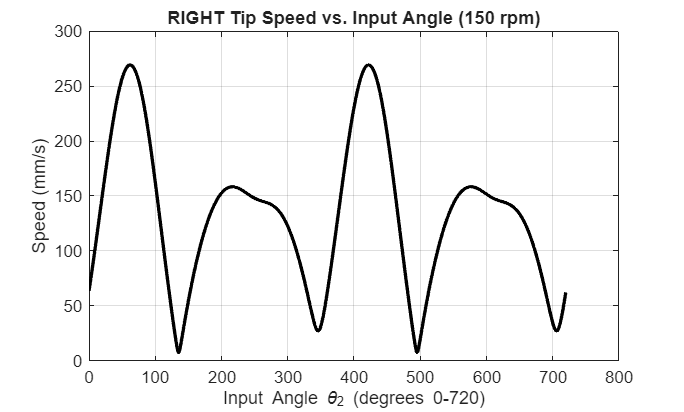

title('RIGHT Tip Speed vs. Input Angle (150 rpm)')
xlabel('Input Angle \theta_2 (degrees 0-720)')
ylabel('Speed (mm/s)')
grid on



fprintf('All analysis complete.\n');

All analysis complete.
